clear all; clc;

lambda = [0.5, 1, 2, 4, 6, 8, 10];   
s_val = (0.0001:0.01:1)'; 


% Compute p once
p = compute_p(lambda);
% If lambda and p are column vectors
T = table(lambda', p', 'VariableNames', {'λ', 'modulus - p'});
disp(T);

     λ     modulus - p
    ___    ___________

    0.5      0.78807  
      1      0.85005  
      2      0.92318  
      4      0.97484  
      6      0.98971  
      8      0.99518  
     10      0.99753  



% Solve for phi_matrix (using the nested loop compute_phi)
phi_results = compute_phi(s_val, lambda, p);

% Create Table with Dynamic Column Titles
% We use '%.1f' since your lambdas have one decimal place
colNames = arrayfun(@(x) sprintf('λ_%.2f', x), lambda, 'UniformOutput', false);

T_phi = array2table(phi_results, 'VariableNames', colNames);

% Add s_Position as the first column for context
T_phi = addvars(T_phi, s_val, 'Before', 1, 'NewVariableNames', 's_Position');

% Display the results
fprintf('--- Phi Values (Radians) for s along the beam ---\n');

--- Phi Values (Radians) for s along the beam ---


disp(T_phi);

    s_Position    λ_0.50    λ_1.00     λ_2.00     λ_4.00     λ_6.00     λ_8.00     λ_10.00
    __________    ______    _______    _______    _______    _______    _______    _______

      0.0001      1.1136    0.98249    0.87261    0.81169    0.79602    0.79045     0.7881
      0.0101      1.1186    0.98955    0.88257    0.82574    0.81319    0.81025     0.8102
      0.0201      1.1236    0.99657    0.89244    0.83959    0.83007    0.82965    0.83181
      0.0301      1.1285     1.0036    0.90223    0.85326    0.84665    0.84866    0.85293
      0.0401      1.1335     1.0105    0.91194    0.86674    0.86294    0.86727    0.87355
      0.0501      1.1384     1.0174    0.92157    0.88003    0.87895     0.8855    0.89368

% Preallocate the theta matrix (same size as phi_results)
theta_results = zeros(size(phi_results));

% Calculate theta for each load case (column)
for j = 1:numel(lambda)
    % Extract the specific p for this load case
    pj = p(j); 
    
    % Extract the entire column of phi for this load case
    phi_col = phi_results(:, j);
    
    % Apply your formula element-wise to the column
    arg = 2 * (pj^2) * (sin(phi_col).^2) - 1;
    theta_results(:, j) = asin(arg);
end

% Create the Table for Theta
colNamesTheta = arrayfun(@(x) sprintf('λ_%.2f', x), lambda, 'UniformOutput', false);
T_theta = array2table(theta_results, 'VariableNames', colNamesTheta);

% Add the s_Position column
T_theta = addvars(T_theta, s_val, 'Before', 1, 'NewVariableNames', 's_Position');

% Display the results
fprintf('\n--- Theta Values (Radians) for s along the beam ---\n');


--- Theta Values (Radians) for s along the beam ---


disp(T_theta);

    s_Position      λ_0.50        λ_1.00        λ_2.00       λ_4.00        λ_6.00       λ_8.00       λ_10.00  
    __________    __________    __________    __________    _________    __________    _________    __________

      0.0001      4.9202e-05    9.4352e-05    0.00016786    0.0002684    0.00033922    0.0003961    0.00044495
      0.0101       0.0049441      0.009479      0.016853     0.026907      0.033958     0.039602      0.044435
      0.0201        0.009789      0.018764      0.033338     0.053145      0.066977     0.078008      0.087427
      0.0301        0.014584      0.027948      0.049624     0.078984      0.099398      0.11562       0.12942
      0.0401        0.019329      0.037033      0.065709     

T_theta_deg = T_theta;
% Convert all columns except the first one (s_Position) to degrees
T_theta_deg{:, 2:end} = rad2deg(T_theta_deg{:, 2:end});
disp('Theta Values in Degrees:');

Theta Values in Degrees:


disp(T_theta_deg);

    s_Position     λ_0.50      λ_1.00      λ_2.00       λ_4.00      λ_6.00      λ_8.00     λ_10.00 
    __________    ________    ________    _________    ________    ________    ________    ________

      0.0001      0.002819    0.005406    0.0096178    0.015378    0.019436    0.022695    0.025494
      0.0101       0.28328     0.54311      0.96561      1.5416      1.9456       2.269       2.546
      0.0201       0.56087      1.0751       1.9101       3.045      3.8375      4.4696      5.0092
      0.0301        0.8356      1.6013       2.8432      4.5255      5.6951      6.6244      7.4154
      0.0401        1.1075      2.1218       3.7649      5.9831      7.5184      8.7337      9.7647
      0.0501        1.3765 

[X_results, Y_results] = reconstruct_shape(s_val, theta_results);
% Create a new table
T_XY = table(s_val, 'VariableNames', {'s_Position'});

for j = 1:numel(lambda)
    % Create formatted strings "(x, y)"
    col_str = arrayfun(@(x,y) sprintf('(%.4f, %.4f)', x, y), ...
        X_results(:,j), Y_results(:,j), 'UniformOutput', false);
    
    % Add to table with appropriate Lambda title
    colName = sprintf('L_%.2f', lambda(j));
    T_XY.(colName) = col_str;
end

disp('Coordinates (x, y) of the deformed configuration for each Load Case:');

Coordinates (x, y) of the deformed configuration for each Load Case:


disp(T_XY);

    s_Position           L_0.50                  L_1.00                  L_2.00                  L_4.00                  L_6.00                  L_8.00                 L_10.00       
    __________    ____________________    ____________________    ____________________    ____________________    ____________________    ____________________    ____________________

      0.0001      {'(0.0000, 0.0000)'}    {'(0.0000, 0.0000)'}    {'(0.0000, 0.0000)'}    {'(0.0000, 0.0000)'}    {'(0.0000, 0.0000)'}    {'(0.0000, 0.0000)'}    {'(0.0000, 0.0000)'}
      0.0101      {'(0.0100, 0.0000)'}    {'(0.0100, 0.0000)'}    {'(0.0100, 0.0001)'}    {'(0.0100, 0.0001)'}    {'(0.0100, 0.0002)'}    {'(0.0100, 0.0002)'}    {'(0.0100, 0.000

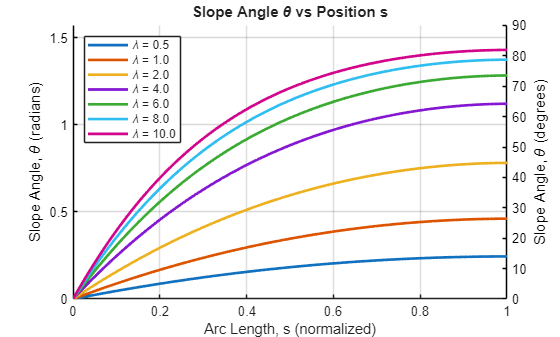

%%%%%   5a   %%%%%
figure;
hold on;

% Define colors to stay consistent
colors = lines(numel(lambda));

% Set the Left Axis for Radians
yyaxis left
for j = 1:numel(lambda)
    % The '-' forces a solid line, and we ensure no markers are defined
    plot(s_val, theta_results(:, j), '-', 'LineWidth', 2, ...
        'Color', colors(j, :), ...
        'DisplayName', sprintf('\\lambda = %.1f', lambda(j)));
end
ylabel('Slope Angle, \theta (radians)');
ylim([0, max(theta_results(:)) * 1.1]); % Set limits with a 10% buffer

% Set the Right Axis for Degrees
yyaxis right
ylabel('Slope Angle, \theta (degrees)');
% Sync the limits so the lines match both scales
ylim([0, rad2deg(max(theta_results(:))) * 1.1]); 

% Common formatting
grid on;
xlabel('Arc Length, s (normalized)');
title('Slope Angle \theta vs Position s');
legend('Location', 'northwest'); % Move legend so it doesn't block the lines

% Match the tick colors to black so they are easy to read
ax = gca;
ax.YAxis(1).Color = 'k';
ax.YAxis(2).Color = 'k';
saveas(gcf, '5-a.png');

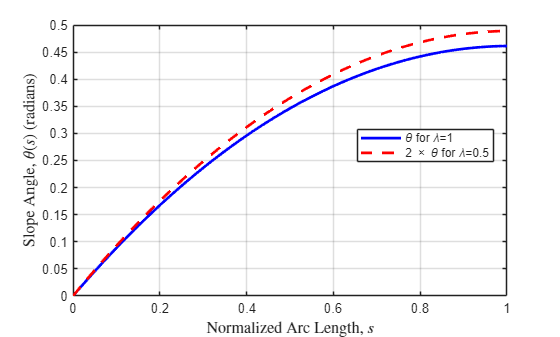

%%%%%   5b   %%%%%
figure;
plot(s_val, theta_results(:, 2), 'b-', 'LineWidth', 2, 'DisplayName', '\theta for \lambda=1');
hold on;
plot(s_val, 2 * theta_results(:, 1), 'r--', 'LineWidth', 2, 'DisplayName', '2 \times \theta for \lambda=0.5');
grid on;
legend(["\theta for \lambda=1", "2 \times \theta for \lambda=0.5"], "Position", [0.6379 0.5195 0.2448, 0.0987])
% Axis Titles and Formatting
xlabel('Normalized Arc Length, $s$', 'Interpreter', 'latex', 'FontSize', 12);
ylabel('Slope Angle, $\theta(s)$ (radians)', 'Interpreter', 'latex', 'FontSize', 12);
saveas(gcf, '5-b.png');

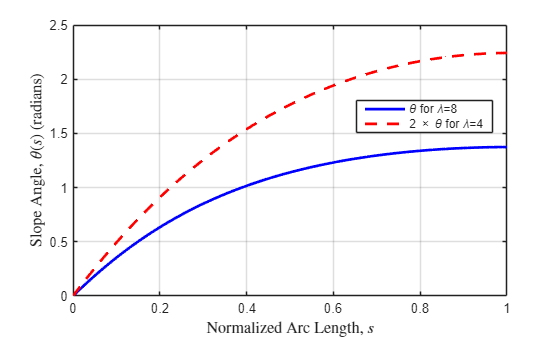

%%%%%   5c   %%%%%
figure;
plot(s_val, theta_results(:, 6), 'b-', 'LineWidth', 2, 'DisplayName', '\theta for \lambda=8');
hold on;
plot(s_val, 2 * theta_results(:, 4), 'r--', 'LineWidth', 2, 'DisplayName', '2 \times \theta for \lambda=4');
grid on;
legend(["\theta for \lambda=8", "2 \times \theta for \lambda=4"], "Position", [0.6379 0.5195 0.2448, 0.0987])
% Axis Titles and Formatting
xlabel('Normalized Arc Length, $s$', 'Interpreter', 'latex', 'FontSize', 12);
ylabel('Slope Angle, $\theta(s)$ (radians)', 'Interpreter', 'latex', 'FontSize', 12);

legend(["\theta for \lambda=8", "2 \times \theta for \lambda=4"], "Position", [0.6361 0.6056 0.2448, 0.0987])
saveas(gcf, '5-c.png');

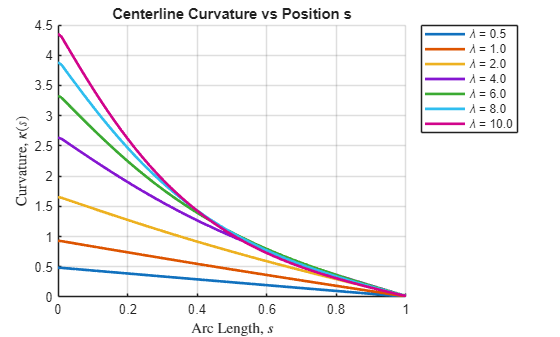

%%%%%   5d   %%%%%
% Calculate Curvature
kappa_results = compute_curvature(s_val, theta_results);

% Create the Plot
figure;
hold on;
colors = lines(numel(lambda));

for j = 1:numel(lambda)
    plot(s_val, kappa_results(:, j), 'LineWidth', 2, ...
        'Color', colors(j, :), ...
        'DisplayName', sprintf('\\lambda = %.1f', lambda(j)));
end

% Formatting
grid on;
xlabel('Arc Length, $s$', 'Interpreter', 'latex');
ylabel('Curvature, $\kappa(s)$', 'Interpreter', 'latex');
title('Centerline Curvature vs Position s');
legend('Location', 'bestoutside');
saveas(gcf, '5-d.png');

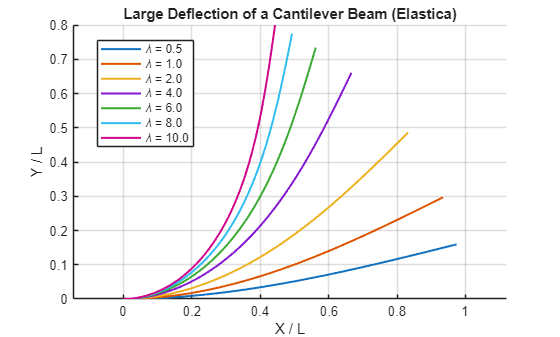

%%%%%   5e   %%%%%
figure;
hold on;
for j = 1:numel(lambda)
    plot(X_results(:, j), Y_results(:, j), 'LineWidth', 1.5, ...
        'DisplayName', sprintf('\\lambda = %.1f', lambda(j)));
end
grid on;
axis equal; % Important: keeps the scale of x and y the same
xlabel('X / L');
ylabel('Y / L');
title('Large Deflection of a Cantilever Beam (Elastica)');
legend('Location', 'best');
saveas(gcf, '5-e.png');

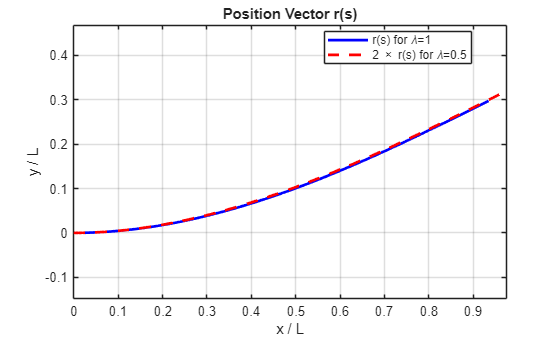

%%%%%   5f   %%%%%
figure;
% Actual shape for lambda = 1
plot(X_results(:, 2), Y_results(:, 2), 'b-', 'LineWidth', 2, 'DisplayName', 'r(s) for \lambda=1');
hold on;
% Linear prediction (2 * shape for lambda = 0.5)
plot(X_results(:, 1), 2*Y_results(:, 1), 'r--', 'LineWidth', 2, 'DisplayName', '2 \times r(s) for \lambda=0.5');

grid on; axis equal;
xlabel('x / L'); ylabel('y / L');
title('Position Vector r(s)');
legend('Location', 'best');
saveas(gcf, '5-f.png');

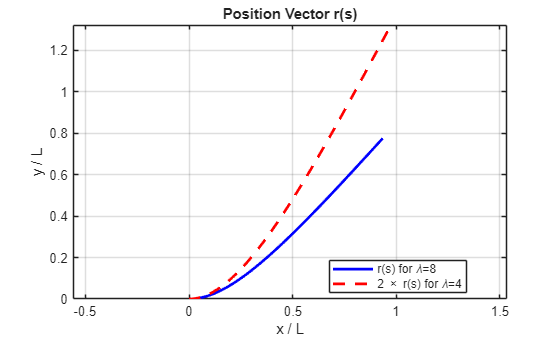

%%%%%   5g   %%%%%
figure;
% Actual shape for lambda = 8
plot(X_results(:, 2), Y_results(:, 6), 'b-', 'LineWidth', 2, 'DisplayName', 'r(s) for \lambda=8');
hold on;
% Linear prediction (2 * shape for lambda = 4)
plot(X_results(:, 1), 2*Y_results(:, 4), 'r--', 'LineWidth', 2, 'DisplayName', '2 \times r(s) for \lambda=4');

grid on; axis equal;
xlabel('x / L'); ylabel('y / L');
title('Position Vector r(s)');
legend('Location', 'best');
saveas(gcf, '5-g.png');

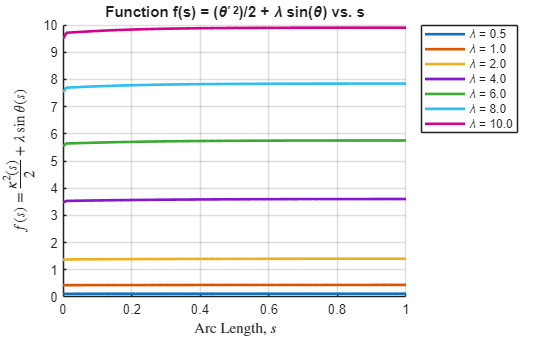

%%%%%   5h   %%%%%
% Preallocate the function matrix
f_s_results = zeros(size(theta_results));

% Calculate f(s) for each load case
for j = 1:numel(lambda)
    lj = lambda(j);
    kj = kappa_results(:, j);
    tj = theta_results(:, j);
    
    % The function as defined in your assignment
    f_s_results(:, j) = (kj.^2 / 2) + (lj * sin(tj));
end

% Plotting
figure;
hold on;
for j = 1:numel(lambda)
    plot(s_val, f_s_results(:, j), 'LineWidth', 2, ...
        'DisplayName', sprintf('\\lambda = %.1f', lambda(j)));
end

grid on;
xlabel('Arc Length, $s$', 'Interpreter', 'latex');
ylabel('$f(s) = \frac{\kappa^2(s)}{2} + \lambda \sin \theta(s)$', 'Interpreter', 'latex');
title('Function f(s) = (\theta^{\prime 2})/2 + \lambda sin(\theta) vs. s');
legend('Location', 'bestoutside');
saveas(gcf, '5-h.png');

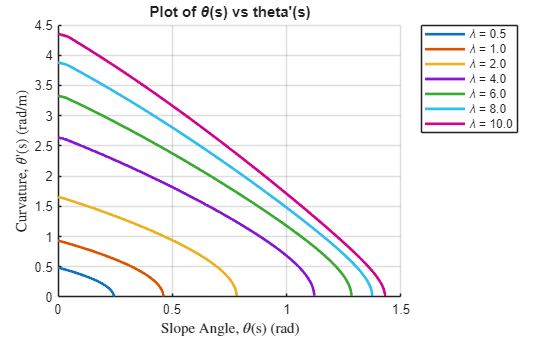

%%%%%   5i   %%%%%
figure; hold on;
for j = 1:numel(lambda)
    % Plotting angle vs curvature
    plot(theta_results(:, j), kappa_results(:, j), 'LineWidth', 2, ...
        'DisplayName', sprintf('\\lambda = %.1f', lambda(j)));
end
grid on;
xlabel('Slope Angle, $\theta$(s) (rad)', 'Interpreter', 'latex');
ylabel('Curvature, $\theta$''(s) (rad/m)', 'Interpreter', 'latex');
title('Plot of \theta(s) vs theta''(s)');
legend('Location', 'bestoutside');
saveas(gcf, '5-i.png');

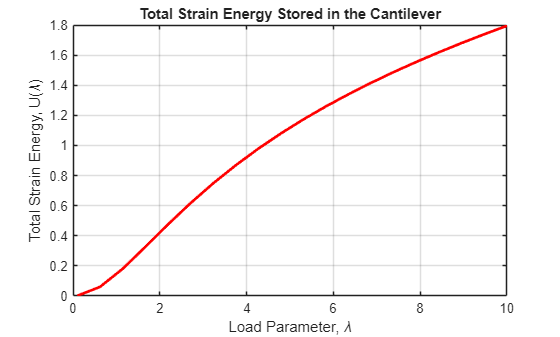

%%%%%   6   %%%%%
% Define the range for lambda
lambda_range = linspace(0.1, 10, 20);

% Preallocate for Strain Energy
U_stored = zeros(size(lambda_range));

for j = 1:numel(lambda_range)
    lj = lambda_range(j);
    
    % Re-calculate p, theta, and kappa for this specific lambda
    pj = compute_p(lj);
    tj = compute_phi(s_val, lj, pj); % Internal phi calculation
    
    % Convert phi to theta (using the formula we established)
    arg = 2 * (pj^2) * (sin(tj).^2) - 1;
    theta_j = asin(arg);
    
    % Calculate Curvature
    kappa_j = gradient(theta_j, s_val);
    
    % Calculate Strain Energy: U = 0.5 * integral(kappa^2 ds)
    U_stored(j) = 0.5 * trapz(s_val, kappa_j.^2);
end

% 3. Plot Total Strain Energy vs Lambda
figure;
plot(lambda_range, U_stored, 'r-', 'LineWidth', 2);
grid on;
xlabel('Load Parameter, \lambda', 'Interpreter', 'tex');
ylabel('Total Strain Energy, U(\lambda)', 'Interpreter', 'tex');
title('Total Strain Energy Stored in the Cantilever');
saveas(gcf, '6.png');

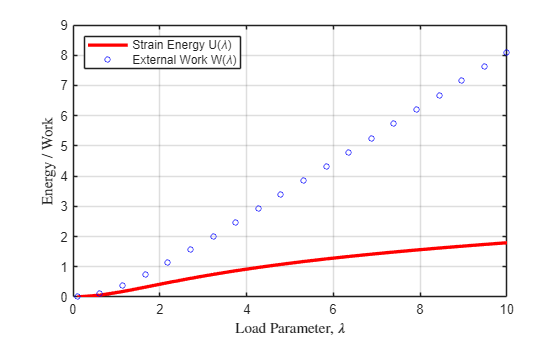

% 1. Range for lambda
lambda_range = linspace(0.1, 10, 20);
s_val = linspace(0, 1, 100)'; % 100 points for integration accuracy

% 2. Preallocate
U_stored = zeros(size(lambda_range));
W_done = zeros(size(lambda_range));

for j = 1:numel(lambda_range)
    lj = lambda_range(j);
    
    % --- SOLVE KINEMATICS ---
    pj = compute_p(lj);
    phi_j = compute_phi(s_val, lj, pj);
    
    % Convert phi to theta: theta = asin(2*p^2*sin(phi)^2 - 1)
    theta_j = asin(2 * pj^2 * (sin(phi_j).^2) - 1);
    
    % --- CALCULATE STRAIN ENERGY (U) ---
    kappa_j = gradient(theta_j, s_val);
    U_stored(j) = 0.5 * trapz(s_val, kappa_j.^2);
    
    % --- CALCULATE EXTERNAL WORK (W) ---
    % Integrate to find Y-coordinate at the tip
    y_coords = cumtrapz(s_val, sin(theta_j));
    y_tip = y_coords(end);
    W_done(j) = lj * y_tip;
end

% 3. Plotting the Comparison
figure;
plot(lambda_range, U_stored, 'r-', 'LineWidth', 2.5, 'DisplayName', 'Strain Energy U(\lambda)');
hold on;
plot(lambda_range, W_done, 'bo', 'MarkerSize', 4, 'DisplayName', 'External Work W(\lambda)');

grid on;
xlabel('Load Parameter, $\lambda$', 'Interpreter', 'latex');
ylabel('Energy / Work', 'Interpreter', 'latex');
legend('Location', 'northwest');
saveas(gcf, '7.png');

% --- Functions Section ---

function p = compute_p(lambda)
    % Preallocate the output vector for efficiency
    p = zeros(size(lambda));
    
    % Define the search range constants
    p_lower = 1/sqrt(2) + 1e-9;
    p_upper = 1 - 1e-9;
    
    % Loop through each element of the input vector
    for i = 1:numel(lambda)
        % Define the function handle for the current lambda(i)
        fun = @(p_val) sqrt(lambda(i)) - ellipke(p_val^2) + ellipticF(asin(1/(p_val*sqrt(2))), p_val^2);
        
        % Solve for p and store it
        try
            p(i) = fzero(fun, [p_lower, p_upper]);
        catch
            p(i) = NaN; % Handle cases where a solution might not exist
            warning('Could not find a solution for lambda = %f', lambda(i));
        end
    end
end

function phi_matrix = compute_phi(s_vec, lambda_vec, p_vec)
    % this function outputs a matrix that contains values of phi(s)
    % along the length for varoius load cases -> p(lambda) 

    % s_vec: Vector of positions along the length (e.g., 0 to 1)
    % lambda_vec: Vector of load parameters
    % p_vec: Vector of parameters corresponding to lambda
    
    num_s = numel(s_vec);
    num_loads = numel(p_vec);
    
    % Preallocate matrix: Rows = positions, Columns = load cases
    phi_matrix = zeros(num_s, num_loads);
    
    for j = 1:num_loads
        % Constants for the current load case
        pj = p_vec(j);
        lj = lambda_vec(j);
        
        phi0 = asin(1/(pj*sqrt(2)));
        F0 = ellipticF(phi0, pj^2);
        
        for i = 1:num_s
            % Target for this specific point s(i) under load j
            target_F = sqrt(lj) * s_vec(i) + F0;
            
            fun = @(phi_val) ellipticF(phi_val, pj^2) - target_F;
            
            try
                % Solve for phi at this specific point
                phi_matrix(i, j) = fzero(fun, [-pi, pi]);
            catch
                phi_matrix(i, j) = NaN;
            end
        end
    end
end

function [X, Y] = reconstruct_shape(s, theta)
    % RECONSTRUCT_SHAPE Calculates spatial coordinates from slope angles
    % s: Vector of arc length positions (n x 1)
    % theta: Matrix of slope angles (n x m) where m is number of load cases
    
    % Preallocate based on the size of theta
    X = zeros(size(theta));
    Y = zeros(size(theta));
    
    % Loop through each load case (each column)
    for j = 1:size(theta, 2)
        % --- COORDINATE RECONSTRUCTION (Numerical Integration) ---
        % dx = cos(theta) * ds, dy = sin(theta) * ds
        % cumtrapz provides the (x, y) position for EVERY point along s
        X(:, j) = cumtrapz(s, cos(theta(:, j)));
        Y(:, j) = cumtrapz(s, sin(theta(:, j)));
        % --- COORDINATE RECONSTRUCTION (Numerical Integration) ---
            % We reconstruct the physical (x, y) shape of the beam from the slope angle theta.
            % Since the beam is inextensible, for a small segment ds:
            % dx = cos(theta) * ds
            % dy = sin(theta) * ds
            %
            % We use 'cumtrapz' to perform a cumulative integration along the arc length (s).
            % Unlike 'trapz' (which gives a single total value), 'cumtrapz' returns a vector
            % of the same size as s, providing the (x, y) position for EVERY point.
            % This allows us to map the 'material' coordinates (s) to 'spatial' coordinates (x, y).
    end
end

function kappa = compute_curvature(s, theta)
    % s: vector of arc length (n x 1)
    % theta: matrix of slope angles (n x m)
    
    % Initialize curvature matrix (n x m)
    kappa = zeros(size(theta));
    
    % Loop through each load case
    for j = 1:size(theta, 2)
        % Numerical derivative: dtheta/ds
        % diff(theta) gives n-1 points, so we use 'gradient' to keep size n
        kappa(:, j) = gradient(theta(:, j), s);
    end
end